% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

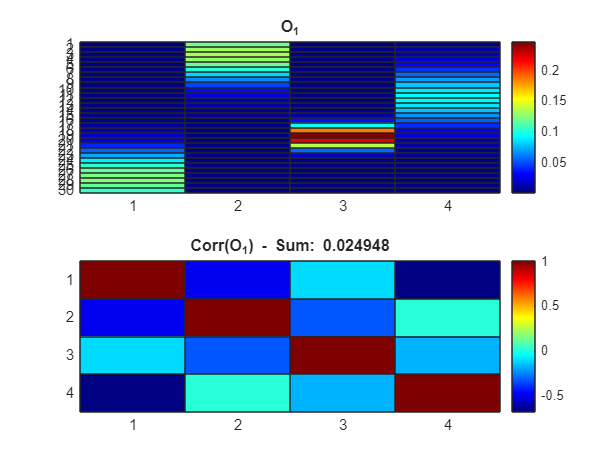

k = 4;
d = 30;
n = 5;

options.method = "random";
options.epsilon = 1/20;

[T, O, pi] = generateHMM(k, d, n, options);


figure(1);
subplot(2,1, 1);
h = heatmap(O{1}, Colormap=jet(), FontSize=10, CellLabelColor="none");
h.Title = ['O_' num2str(1)];


covMat = corrcoef(O{1});

subplot(2,1,2);
h = heatmap(covMat, Colormap=jet(), FontSize=10, CellLabelColor="none");
h.Title = ['Corr(O_' num2str(1) ') - Sum: ' num2str(sum(covMat, "all")/size(covMat, 1)^2)];

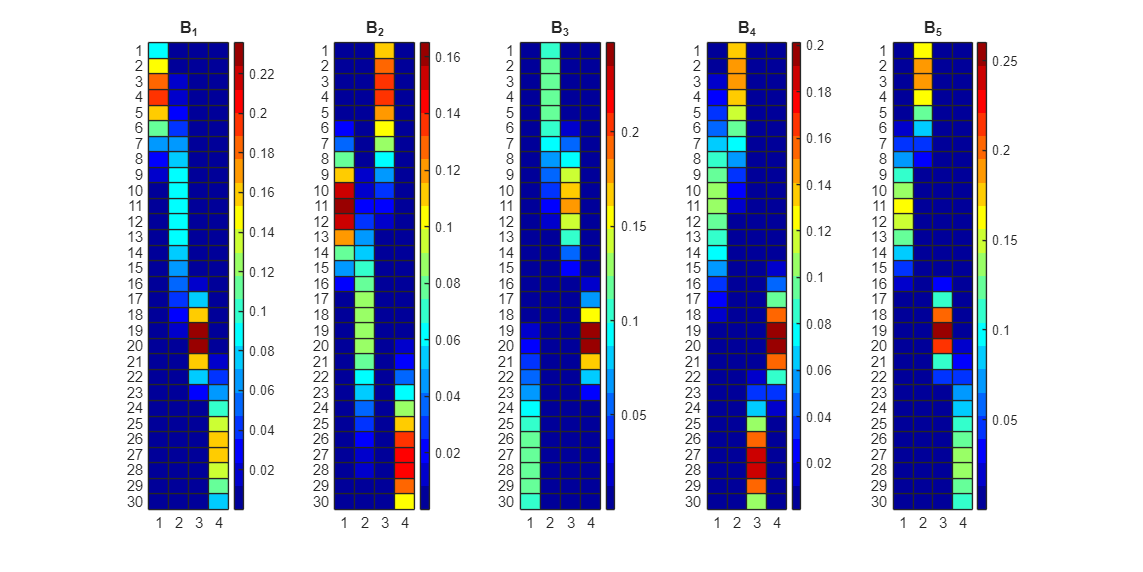



if(n < 5)
    figure('Renderer', 'painters', 'Position', [10 10 1500 1000])

    subplot(1, n+1, 1);
    h = heatmap(T, Colormap=jet());
    h.Title = 'T';
    
    for i = 1:n
        subplot(1, n+1, i+1);
        h = heatmap(O{i}, Colormap=jet());
        h.Title = ['O ' num2str(i)];
    end
end
PlotFactorMatrices(O);

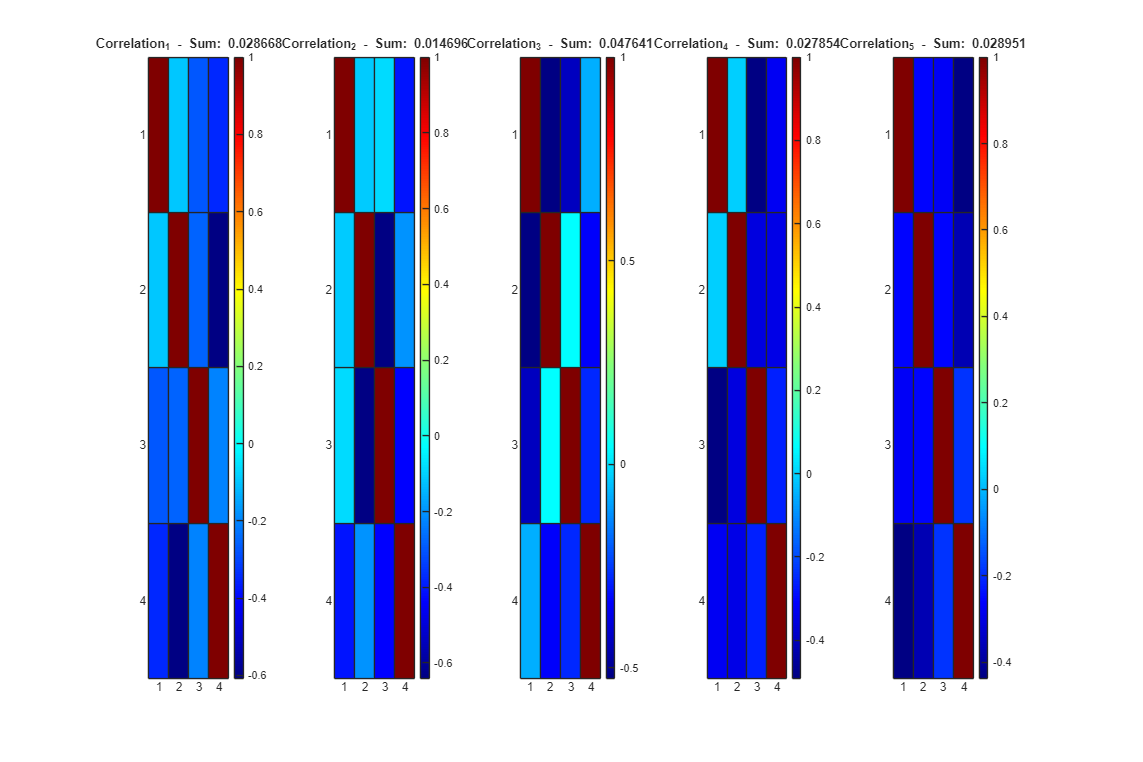

plotCovarianceMatrices(O);

Generate an observational sequence based on the defined HMM

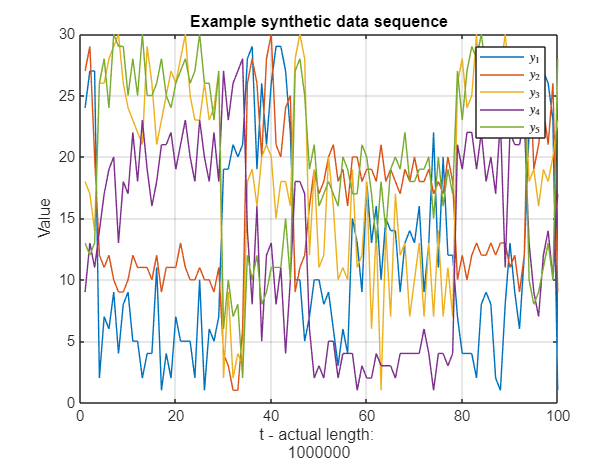


T_seq = 1e6;
P3 = cell(1, n);

use_optimal_JPT = false;

if use_optimal_JPT
    for i = 1:n
        U = {};
        U{1} = (O{i} * diag(pi) * T' / inv(diag(T * pi')));
        U{2} = O{i};
        U{3} = (O{i} * T);
        P3{i} = cpdgen(U)/k;
    end
else
    [seq, states] = generate_multivariate_hmm_sequence(T, O, pi, T_seq);
    for i = 1:n
        P3{i} = ProbabilityTensorGenerate(seq(i, :), 3, d);
    end
end


figure()
plot(seq(:, 1:100)')
title("Example synthetic data sequence")
ylabel("Value")
xlabel(["t - actual length: " T_seq])
legendLabels = arrayfun(@(i) sprintf('$$y_{%d}$$', i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex');
grid on;

## Run seperate CPDs


O_hats = cell(n, 1);
T_hats = cell(n, 1);
T_hat = zeros(size(T));

epsilon = 1e-7;

options.maxIter = 500;
options.th_relerr = 1e-7;

tic
for i = 1:n
    [A, B, C, ~, output] = cpd_als_3d(P3{i}, k, options);
    O_hat = Stochasticize(B);
    T_hats{i} = Stochasticize(pinv(Stochasticize(B)) * Stochasticize(C));

    Pbest = PermutationFit(T, T_hats{i}, true);
    T_hats{i} = Pbest * T_hats{i} * Pbest';
    T_hat = T_hat + (1/n) * T_hats{i};

    O_hats{i} = O_hat * Pbest';
end

Undefined variable 'P3'.

toc

PlotFactorMatrices(T_hats)


HMMError(T, O, T_hat, O_hats, true)


options.maxIter = 2500;
options.tol = 1e-16;

alpha = 0.1;
rho = 0.85;

tic
[T_hat, O_hats, pi_hat, output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, options);
toc

Elapsed time is 7.637884 seconds.


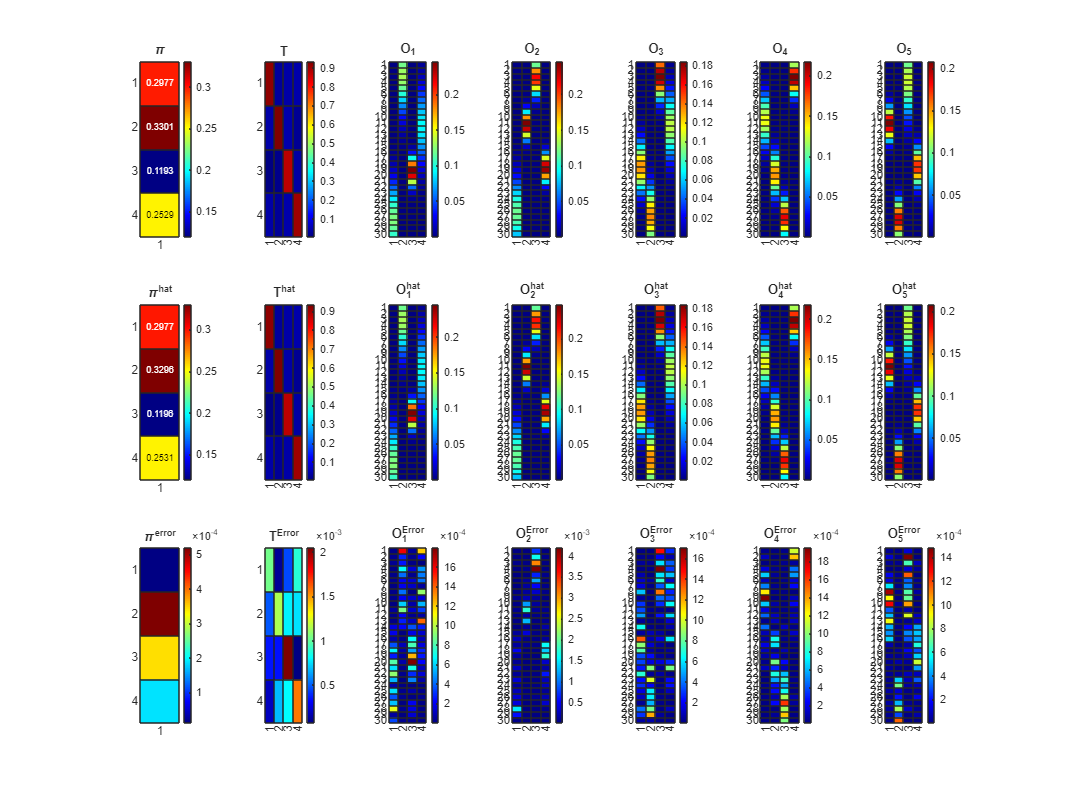

ans = 0.0093


[T_hat, O_hats, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hats, pi_hat);
HMMError(T, O, T_hat, O_hats, true)

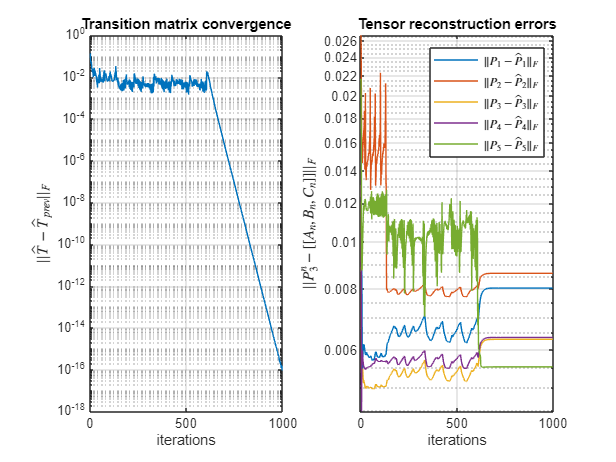


figure()
subplot(1, 2, 1);
semilogy(output.tconv);
title("Transition matrix convergence")
ylabel("$||\hat{T} - \hat{T}_{prev}||_F$", "Interpreter","latex")
xlabel("iterations")
grid on;

subplot(1, 2, 2);
semilogy(output.recerr')
title("Tensor reconstruction errors")
ylabel("$||P_3^n - [[A_n, B_n, C_n]]||_F$", "Interpreter","latex")
xlabel("iterations")
legendLabels = arrayfun(@(i) sprintf('$$\\|P_{%d} - \\hat{P}_{%d}\\|_F$$', i, i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex');
grid on;


plotCovarianceMatrices(O_hats)